# Support Vector Machines

clear; 
close all; 
clc;

%Load the data
T = csvread('../Data/Ex3Data.csv');

X = T(:,1:2);
Y = T(:,3);

Play with the parameters of support vector machines

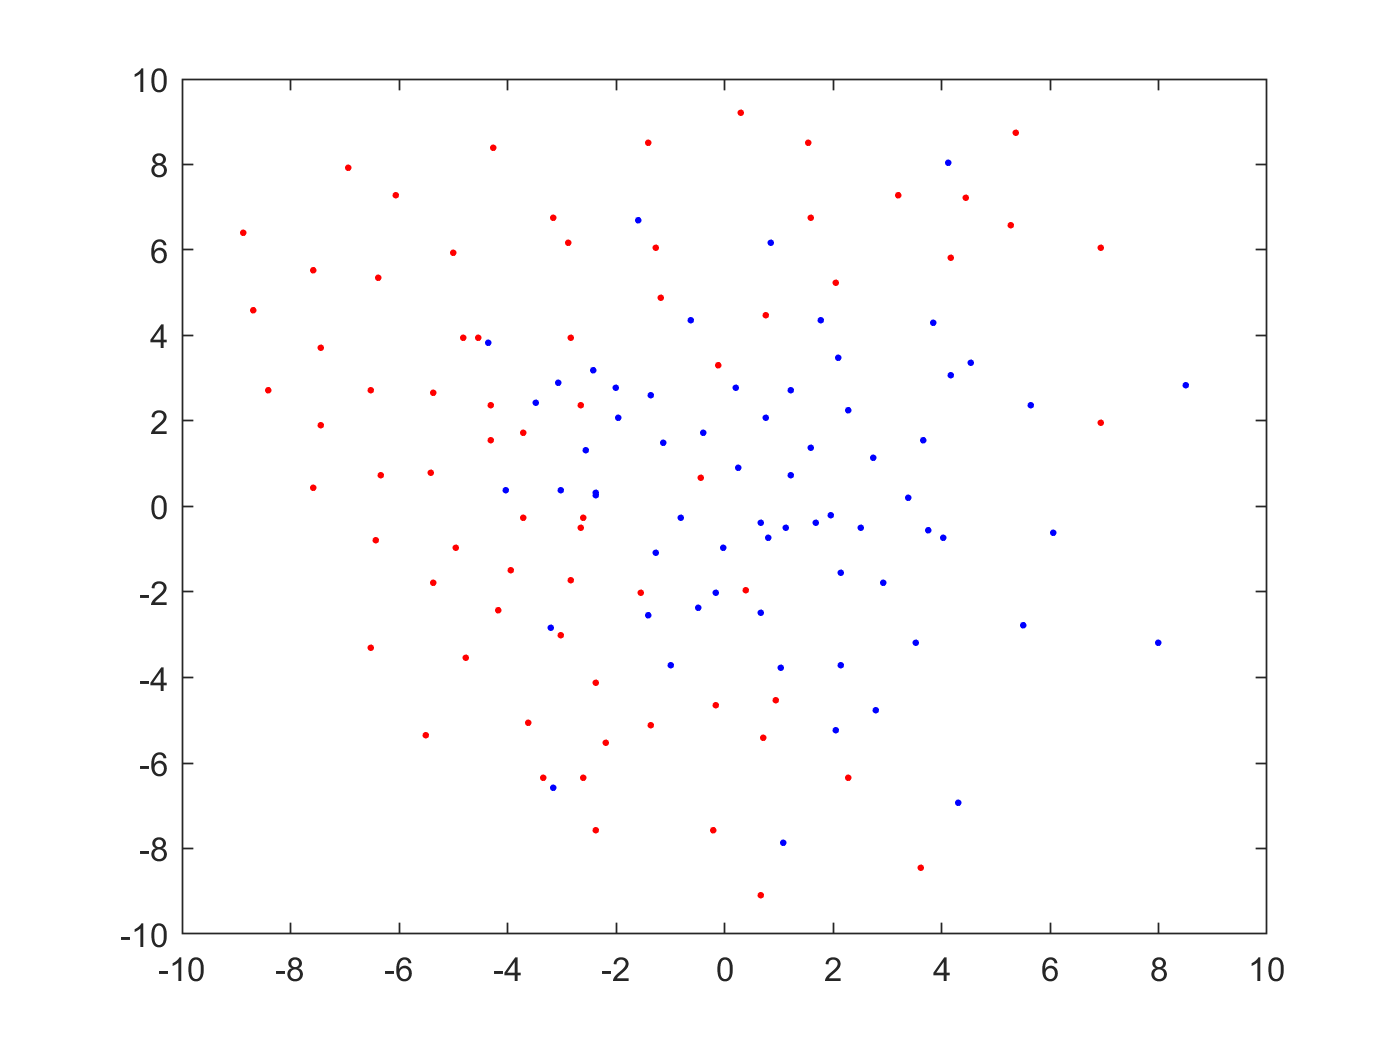

KernelFunction  = 'rbf';
KernelScale     = 0.5;
PolynomialOrder = 2;
BoxConstraint   = 10000;

% Estimate model
switch KernelFunction
    case 'rbf'
        %%% Add you code here
        %Fit svm. Name your model svm
        
        %%%
    case 'polynomial'
        %%% Add you code here
        %Fit svm. Name your model svm
        
        %%% 
    case 'linear'
        %%% Add you code here
        %Fit svm. Name your model svm
        
        %%% 
    otherwise
        disp(' Unsupported kernel');
end

% Draw observations
figure
plot(X(Y==1,1),X(Y==1,2),'b.')
hold on
plot(X(Y==-1,1),X(Y==-1,2),'r.')


%Draw decision lines
h = 0.1; 
[X1,X2] = meshgrid(-10:h:10,-10:h:10);
[~,score] = predict(svm,[X1(:),X2(:)]);

Unrecognized function or variable 'svm'.

scoreGrid = reshape(score(:,2),size(X1,1),size(X2,2));
[~, h] = contour(X1,X2,scoreGrid,[0 0]); %Draw the decision line
set(h,'linecolor','k','linewidth',2)
[~, h] = contour(X1,X2,scoreGrid,[1 1]); %Draw margin
set(h,'linecolor','k')
[~, h] = contour(X1,X2,scoreGrid,[-1 -1]); %Draw margin
set(h,'linecolor','k')

% Draw support points
I = svm.IsSupportVector;
Xactive = X(I,:);
Isupportpoint = svm.Alpha>1e-6 & svm.Alpha<(BoxConstraint-1e-6);
plot(Xactive(Isupportpoint,1), Xactive(Isupportpoint,2), 'ks');
hold off

If you want to optimize the hyperparameters, this can be done automatically by fitcsvm using the input 'Optimizehyperparameters'. You can cross-validate your SVM classifier ysing the functions 'crossval()' and 'kfoldLoss()'. Check out the 'fitcsvm' documentation for more.